# Space Mechanics (086287) – HW2 

Olga Ioffe

HW from semester: Winter 2017-18

Revised: Oct. 2024

Matlab ver.: 2024b

### Initialization

clear
close all
clc

### Constants

mu = 3.98603e5; %km^3/sec^2, from Appendix A
Re = 6378.16; %km

## Question 1

### Problem:

Given:

Original orbit:

T = 120*60; %sec

At descending node:

rx_des = 5300; % [km]
ry_des = 6100; % [km]
rz_des = 0;
Vx_des = -1.5; % [km/s]
Vy_des = 2.2;  % [km/s]
Vz_des = -6.4887; % [km/s]

At ascending node tangential velocity pulse of 10m/sec is applied:

deltaVt_asc = 10e-3; % [km/sec]

Find:

a. a, e  and i of the new orbit

b. position and velocity 20 min. after pulse applied

### Preliminary calculations

#### r at desending node:

rdes_vec = [rx_des;ry_des;rz_des];
Vdes_vec = [Vx_des;Vy_des;Vz_des];
rdes = norm(rdes_vec);

#### Original orbit data (p, E, h, e, inclination, $\omega$, $\Omega$):

a_orig = (T^2*mu/4/pi^2)^(1/3); % [km]

h_vec_orig = cross(rdes_vec,Vdes_vec);
h_orig = norm(h_vec_orig);

En_orig = -mu/2/a_orig;

p_orig = h_orig^2/mu;

e_vec_orig = 1/mu*cross(Vdes_vec,h_vec_orig)-rdes_vec/rdes;
e_orig = sqrt(1-h_orig^2/mu/a_orig);

cos_inclination = h_vec_orig(3)/h_orig;
inclination = acos(cos_inclination);
inclination_deg = inclination*180/pi 

inclination_deg = 68.3529

Calculating Omega and omega of the original orbit.


$$\left\lbrack \begin{array}{c}
h_x \\
h_y \\
h_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{hsin}\left(\Omega \right)\sin \left(i\right)\\
-\textrm{hcos}\left(\Omega \right)\sin \left(i\right)\\
\textrm{hcos}\left(i\right)
\end{array}\right\rbrack$$


sin_Omega = h_vec_orig(1)/h_orig/sin(inclination);
cos_Omega = -h_vec_orig(2)/h_orig/sin(inclination);
Omega_orig = calcAngle(sin_Omega,cos_Omega);
Omega_orig_deg = Omega_orig*180/pi %deg

Omega_orig_deg = 229.0142


$$\left\lbrack \begin{array}{c}
e_x \\
e_y \\
e_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
e\left(\cos \left(\Omega \right)\cos \left(\omega \right)-\sin \left(\Omega \right)\sin \left(\omega \right)\cos \left(i\right)\right)\\
e\left(\sin \left(\Omega \right)\cos \left(\omega \right)+\cos \left(\Omega \right)\sin \left(\omega \right)\cos \left(i\right)\right)\\
\textrm{esin}\left(\omega \right)\sin \left(i\right)
\end{array}\right\rbrack$$


sin_omega = e_vec_orig(3)/e_orig/sin(inclination);
cos_omega = (e_vec_orig(1)/e_orig+sin_Omega*sin_omega*cos_inclination)/cos_Omega;
omega_orig = calcAngle(sin_omega,cos_omega);
omega_orig_deg = omega_orig*180/pi

omega_orig_deg = 82.8153

Orderly output of the original orbit data:

rowNames = {'a';    'h';      'En';        'p';    'e';     'inclination';    'Omega';        'omega'};
Column1 =  [a_orig;  h_orig;   En_orig;     p_orig; e_orig;  inclination_deg;  Omega_orig_deg; omega_orig_deg];
Column2 =  {'[km]'; '[km^2]'; '[m^2/s^2]'; '[km]'; '[ ]';   '[deg]';          '[deg]';        '[deg]'};
T = table(Column1, Column2, 'rowNames', rowNames,'VariableNames',["Value","Units"]);
disp(T)

                    Value          Units    
                   ________    _____________

    a                  8059    {'[km]'     }
    h                 56413    {'[km^2]'   }
    En               -24.73    {'[m^2/s^2]'}
    p                7983.9    {'[km]'     }
    e              0.096559    {'[ ]'      }
    inclination      68.353    {'[deg]'    }
    Omega            229.01    {'[deg]'    }
    omega            82.815    {'[deg]'    }



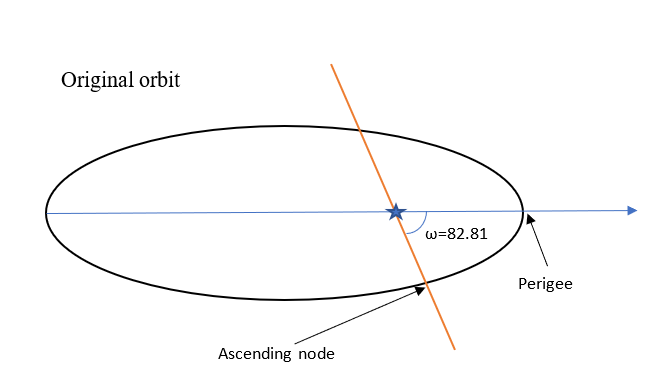

#### DCM-s:

Constructing DCM from perifocal coordinated to ECI for original orbit:

PERIFOC2ECI_orig = [cos(Omega_orig)*cos(omega_orig)-sin(Omega_orig)*sin(omega_orig)*cos(inclination), -cos(Omega_orig)*sin(omega_orig)-sin(Omega_orig)*cos(omega_orig)*cos(inclination),  sin(Omega_orig)*sin(inclination);...
                    sin(Omega_orig)*cos(omega_orig)+cos(Omega_orig)*sin(omega_orig)*cos(inclination), -sin(Omega_orig)*sin(omega_orig)+cos(Omega_orig)*cos(omega_orig)*cos(inclination), -cos(Omega_orig)*sin(inclination);...
                    sin(omega_orig)*sin(inclination),                                        cos(omega_orig)*sin(inclination),                                        cos(inclination)];

Finding the radius and velocity at ascending node:

The true anomaly of the ascending node is

theta_asc_orig = 2*pi-omega_orig;
theta_asc_orig_deg = theta_asc_orig*180/pi;

DCM from polar to cartesian coordinates at this point:

POLAR2CARTES_orig_asc = [cos(theta_asc_orig), -sin(theta_asc_orig), 0;...
                         sin(theta_asc_orig),  cos(theta_asc_orig), 0;...
                         0,                    0,                   1];

#### Ascending node raduis and velovity vectors:

The corresponding radius:

r_asc = p_orig/(1+e_orig*cos(theta_asc_orig));
r_vec_asc_polar= [r_asc; 0; 0];
r_vec_asc_PERIFOC = POLAR2CARTES_orig_asc*r_vec_asc_polar;
r_vec_asc_ECI = PERIFOC2ECI_orig*r_vec_asc_PERIFOC;

The radial and tangential components of V, in polar coordinates are:


$$V_t=\frac{\mu}{h}\left(1+e cos\theta\right)\\
V_r=\frac{\mu}{h}e sin\theta$$


Vt_asc_orig = mu/h_orig*(1+e_orig*cos(theta_asc_orig));
Vr_asc_orig = mu/h_orig*e_orig*(sin(theta_asc_orig));
V_vec_asc_orig_polar= [Vr_asc_orig; Vt_asc_orig; 0];
V_vec_asc_orig_ECI = PERIFOC2ECI_orig*POLAR2CARTES_orig_asc*V_vec_asc_orig_polar;

## Solution a - new orbit prameters

Since the pulse is applied in the plane of the original orbit, the new orbit will have the same inclination.

Also, this is a one pulse maneuvre. Therefore the point where the pulse is applied, is shared by both trajectories. And so ascending node angle, Omega, is the same.

The following calculations will be performed in polar coordinates.

Vt_new = Vt_asc_orig + deltaVt_asc;
V_vec_asc_new_polar = [Vr_asc_orig;Vt_new;0];
V_new = norm(V_vec_asc_new_polar);

Using energy equation:


$$\frac{V^2}{2}-\frac{\mu}{r}=-\frac{\mu}{2a}$$


and then same calculations as for original orbit yeld the new orbit parameters:

a_new = -mu/2/(V_new^2/2-mu/r_asc);
h_vec_new_polar = cross(r_vec_asc_polar,V_vec_asc_new_polar);
h_new = norm(h_vec_new_polar);
e_new = sqrt(1-h_new^2/mu/a_new);
c_new = a_new*e_new;
b_new = a_new*sqrt(1-e_new^2);
En_new = -mu/2/a_new;
p_new = h_new^2/mu;
cos_theta_asc_new = (1-p_new/r_asc)/e_new;

Since Vr<0 after the pulse - the satelite is moving from apgee to perigee.

theta_asc_new = 2*pi-acos(cos_theta_asc_new);
theta_asc_new_deg = theta_asc_new*180/pi;
omega_new = 2*pi - theta_asc_new;
omega_new_deg = omega_new*180/pi;

Orderly output of the new orbit data:

rowNames = {'a';    'h';      'En';        'p';    'e';     'inclination';    'Omega';        'omega'};
Column1 =  [a_new;  h_new;   En_new;     p_new; e_new;  inclination_deg;  Omega_orig_deg; omega_new_deg];
Column2 =  {'[km]'; '[km^2]'; '[m^2/s^2]'; '[km]'; '[ ]';   '[deg]';          '[deg]';        '[deg]'};
T = table(Column1, Column2, 'rowNames', rowNames,'VariableNames',["Value","Units"]);
disp(T)

                    Value          Units    
                   ________    _____________

    a                8082.4    {'[km]'     }
    h                 56492    {'[km^2]'   }
    En              -24.659    {'[m^2/s^2]'}
    p                8006.2    {'[km]'     }
    e              0.097086    {'[ ]'      }
    inclination      68.353    {'[deg]'    }
    Omega            229.01    {'[deg]'    }
    omega            98.834    {'[deg]'    }



Constructing new DCM

PERIFOC2ECI_new = [cos(Omega_orig)*cos(omega_new)-sin(Omega_orig)*sin(omega_new)*cos(inclination), -cos(Omega_orig)*sin(omega_new)-sin(Omega_orig)*cos(omega_new)*cos(inclination),  sin(Omega_orig)*sin(inclination);...
                   sin(Omega_orig)*cos(omega_new)+cos(Omega_orig)*sin(omega_new)*cos(inclination), -sin(Omega_orig)*sin(omega_new)+cos(Omega_orig)*cos(omega_new)*cos(inclination), -cos(Omega_orig)*sin(inclination);...
                   sin(omega_new)*sin(inclination),                                       cos(omega_new)*sin(inclination),                                       cos(inclination)];
POLAR2CARTES_new_asc = [cos(theta_asc_new), -sin(theta_asc_new), 0;...
                        sin(theta_asc_new),  cos(theta_asc_new), 0;...
                         0,                    0,                   1];                                  

## Solution b - r and V 20 mins later

I - Numerical Integration of equations of motion

In polar coordinates, perifocal plane


$$\bar{x} =\left\lbrack \begin{array}{c}
r\\
\theta \\
\dot{r} \\
\dot{\theta} 
\end{array}\right\rbrack \Rightarrow \dot{\bar{x} } =\left\lbrack \begin{array}{c}
x_3 \\
x_4 \\
-\frac{\mu }{x_1^2 }+x_1 \cdot x_4^2 \\
-2\frac{x_3 x_4 }{x_1 }
\end{array}\right\rbrack$$


Which is implemented in the function 'EOM_polar.m'

Solve for 20 minutes

delta_t = 20*60; %sec
[t,X]=ode45(@(t,y) EOM_polar(t, y, mu),[0 delta_t],[r_asc,theta_asc_new,Vr_asc_orig,Vt_new/r_asc]);
r_20m = X(end,1)

r_20m = 7.3140e+03

theta_20m= X(end,2);
theta_20m_deg = theta_20m*180/pi

theta_20m_deg = 329.4459

r_vec_20m_polar = [r_20m;0;0];
V_vec_20m_polar = [X(end,3);X(end,1)*X(end,4);0];

Converting to cartesian axes:

POLAR2CARTES_f = [cos(theta_20m), -sin(theta_20m), 0;...
                  sin(theta_20m),  cos(theta_20m), 0;...
                  0,              0,             1];
r_vec_20m_PRF = POLAR2CARTES_f*r_vec_20m_polar;
V_vec_20m_PRF = POLAR2CARTES_f*V_vec_20m_polar;

Converting to ECI:

r_vec_20m_ECI = PERIFOC2ECI_new*r_vec_20m_PRF

r_vec_20m_ECI = 1.0e+03 *

    0.1168
   -3.6872
    6.3155


V_vec_20m_ECI = PERIFOC2ECI_new*V_vec_20m_PRF

V_vec_20m_ECI =     5.4996
    4.8019
    2.5249


Conservation of momentum and energy

h_vec_20m = cross(r_vec_20m_ECI,V_vec_20m_ECI);
h_20m = norm(h_vec_20m);
V_20m = norm(V_vec_20m_ECI);
En_20m = V_20m^2/2-mu/r_20m;
fprintf('Initial values: h1 = %5.2f, En = %5.4f\n\n',h_new,En_new)

Initial values: h1 = 56491.62, En = -24.6587



fprintf('Values after numerical Integration: h2 = %5.2f, En = %5.4f\n',h_20m,En_20m)

Values after numerical Integration: h2 = 56491.62, En = -24.6587


II - Using F,G functions

For Newton's method define function f(E) and first derivative


$$f(E)= \sqrt{\frac{a^3}{\mu}}\left(E-e\sin(E)-E_0+e\sin(E_0)\right)-\Delta t\\
f'(E)= \sqrt{\frac{a^3}{\mu}}\left(1-e\cos(E)\right)\\
\Delta E_i = -\frac{f(E)}{f'(E)}$$


Which is implemented in 'Newton_E.m'

cos_E0 = (e_new+cos_theta_asc_new);

E0 is in the same quadrant as inital theta

E0 = 2*pi-acos(cos_E0);
E_f =  Newton_E(a_new,e_new,mu,E0,delta_t)

E_f = 5.7458

Now calculate the corresponding theta. From numerical integration we know it is still before the perigee:

cos_theta_final = (cos(E_f)-e_new)/(1-e_new*cos(E_f));
theta_final = 2*pi-acos(cos_theta_final)

theta_final = 5.6938

delta_theta = theta_final - theta_asc_new

delta_theta = 1.1356

Calculating the new r:

r_final = p_new/(1+e_new*cos_theta_final)

r_final = 7.4083e+03

Calculating F,G,Ft,Gt from their formulae:

F = 1-r_final/p_new*(1-cos(delta_theta));
G = r_final*r_asc/h_new*sin(delta_theta);
Ft = sqrt(mu/p_new)*tan(delta_theta/2)*((1-cos(delta_theta))/p_new-1/r_final-1/r_asc);
Gt = 1-r_asc/p_new*(1-cos(delta_theta));

Sanity check - the following should be ==1

disp(F*Gt-G*Ft)

    1.0000



Finally, using F and G find the final r and V vectors:

r_vec_20m_FG = F*r_vec_asc_ECI+G*V_vec_asc_orig_ECI

r_vec_20m_FG = 1.0e+03 *

   -0.1204
   -3.9116
    6.2352


V_vec_20m_FG = Ft*r_vec_asc_ECI+Gt*V_vec_asc_orig_ECI

V_vec_20m_FG =     5.4603
    4.5545
    2.8589


Conservation of momentum and energy

h_vec_20m_FG = cross(r_vec_20m_FG,V_vec_20m_FG);
h_20m_FG = norm(h_vec_20m_FG);
r_20m_FG = norm(r_vec_20m_FG);
V_20m_FG = norm(V_vec_20m_FG);
En_20m_FG = V_20m_FG^2/2-mu/r_20m_FG;

fprintf('Initial values: h1 = %5.2f, En = %5.4f\n\n',h_new,En_new)

Initial values: h1 = 56491.62, En = -24.6587



fprintf('Values using F,G: h2 = %5.2f, En = %5.4f\n',h_20m_FG,En_20m_FG)

Values using F,G: h2 = 56412.74, En = -24.7807


### Functions:

function dX = EOM_polar(t, y, mu)

dX = zeros(4,1);

x1  = y(1);
x2  = y(2);
x3  = y(3);
x4  = y(4);


dX = [x3;...
      x4;...
      -mu/(x1^2)+x1*x4^2;...
      -2*x3*x4/x1];

end

function E =  Newton_E(a,e,mu,E0,dt)

%Set an error tolerance:
error = 1.e-8;
%Select a starting value for E:
dE = 1;
E =E0+dE;
ind = 0;
%Iterate until E is determined to within the error tolerance:
while abs(dE) > error
    dE = (sqrt(a^3/mu)*(E - e*sin(E) - E0 + e*sin(E0))-dt)/(sqrt(a^3/mu)*(1 - e*cos(E)));
    E = E - dE;
   ind = ind+1;
 
end
end